**Curso: Profundizacion 2: Electromedicina.**

Nombre: Edwin Leandro Ramos Zambrano.

Universidad de Nariño.

**Imagenes-- Transformaciones básicas.**

Limpiar Entorno 

clc
close all
clear variables 

Importar imagen (es necesario agregar la ruta especifica de la imagen, o en su defecto ubicarla en el entorno de trabajo y quitar la ruta del comando.)

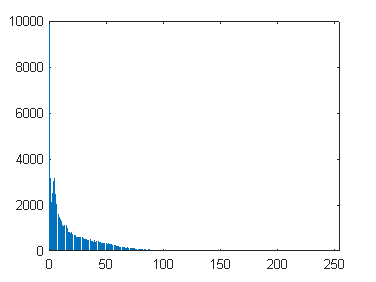

I = imread("C:\Users\elean\Documents\MATLAB\electromedicina2\imagenes\esqueleto.jpg");
I = rgb2gray(I);  % Convertir imagen a escala de gris
[mf, nc] = size(I);  % tamaño de la imagen

h = imhist(I);
L = 0:255;
stem(L, h, "Marker","none");
xlim([0 255]);
ylim([0 10000]);

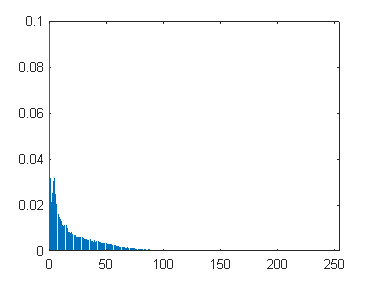

%probabilidad de los niveles de gtris

P = h/(mf*nc);
stem(L, P, "Marker","none");
xlim([0 255]);
ylim([0 0.1]);

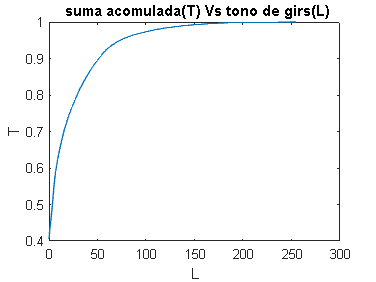


Ic = ecualizar_imagen(I);

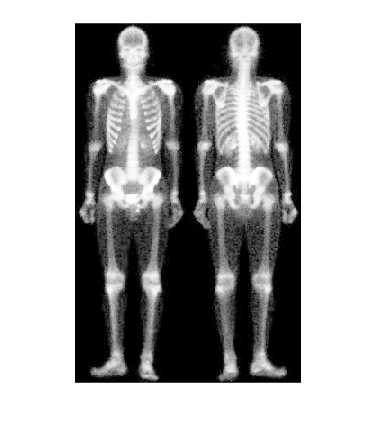

imshow(Ic, []);

% %hacer funcion ecualizacion 
% T = cumsum(P);
% for i = 1: mf
%     for j = 1: nc
%         pixel = I(i, j);
%         nuevopixel(i, j) = T(pixel +1)*255;
%     end
% end
% 
% imshow(nuevopixel,[]);
% imhist(uint8(nuevopixel));